# Predict Behaviour from Ca2+ signal using Machine learning

To see whether the information contained in the dendritic tree is able to predict the current behavioural state of the animal, we can try to use classification or regression between the Ca2+ signal and some behavioural metrics.

## Predictors

The approach requires some predictors, which, in our case are obtained from the GCaMP signal obtained from different part of the dendritic tree. We can use either the entire dendritic tree, or a subset of ROIs from the dendritic tree, or the average between different groups of ROIs (obtained, for example from a previous clustering analysis)

## Predictors preprocessing

Predictors correspond to Ca2+ signal. However, a number of preprocessing steps can be used:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use the obj.rescaled_traces variables (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Observations

If we want to predict the behaviour from the Ca2+, we can use obj.behaviours. Classifiers require a binnarization step, while regression do not

## Example : SVM classifier on all behaviours


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
total dendritic length (-excluded branches) : 1635 um
total dendritic length (-excluded branches) : 1913 um
total dendritic length (-excluded branches) : 1635 um
total dendritic length (-excluded branches) : 1913 um
total dendritic length (-excluded branches) : 1635 um
total dendritic length (-excluded branches) : 1913 um
total dendritic length (-excluded branches) : 1635 um
total dendritic length (-excluded branches) : 1913 um
total dendritic length (-excluded branches) : 1635 um
total dendritic length (-excluded branches) : 1913 um
total dendritic length (-excluded branches) : 1635 um
total dendritic 

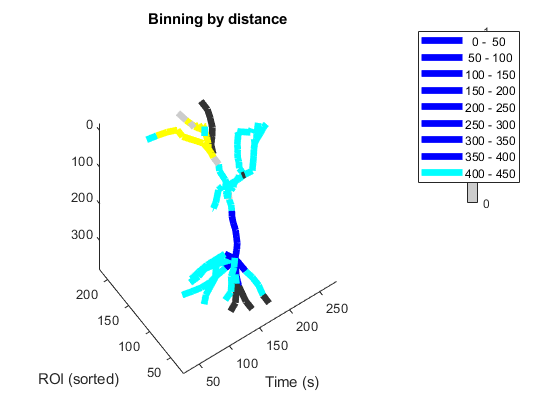

Now detecting events with global pairwise correlation at least > 0.2 % 
    * Events detection is using PAIRWISE CORRELATION between all provided traces 
      Epochs of correlated changes of activity across a set % of the tree/pop will be considered as an event 


THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 56.9712%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 202 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 5events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


RECOVERY_THR = 0.8000

!!! ROIs 23 was/were excluded but seem highly correlated
The model out-of-sample misclassification rate is 32.8%


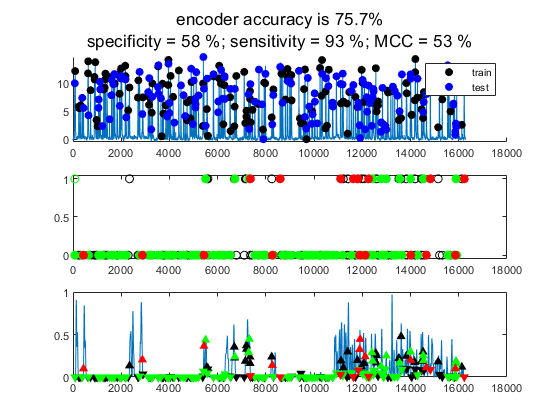

The model out-of-sample misclassification rate is 41.8%


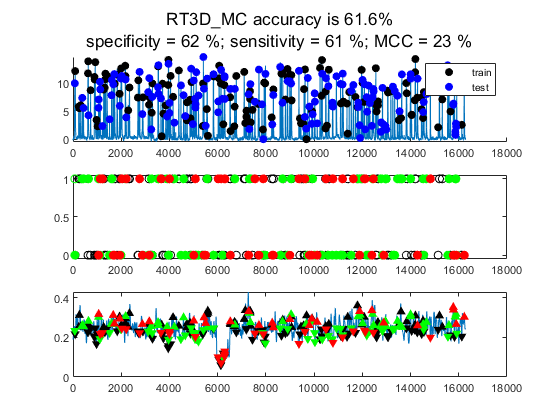

The model out-of-sample misclassification rate is 44.2%


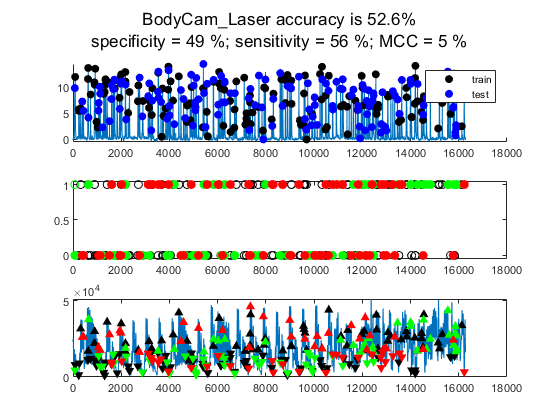

The model out-of-sample misclassification rate is 31.9%


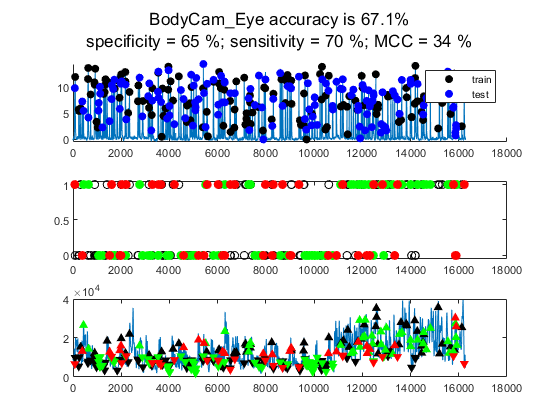

The model out-of-sample misclassification rate is 27.6%


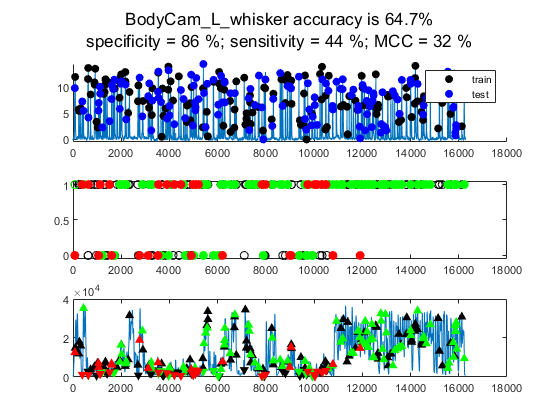

The model out-of-sample misclassification rate is 24.5%


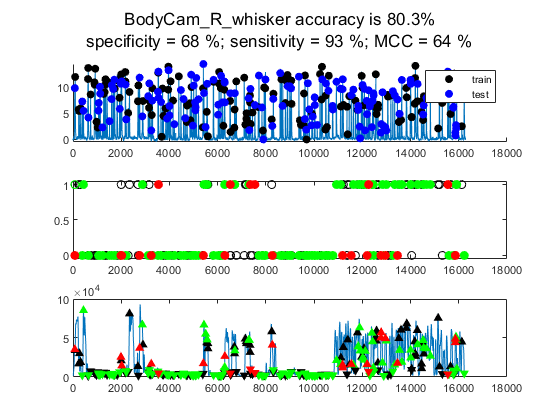

The model out-of-sample misclassification rate is 38.3%


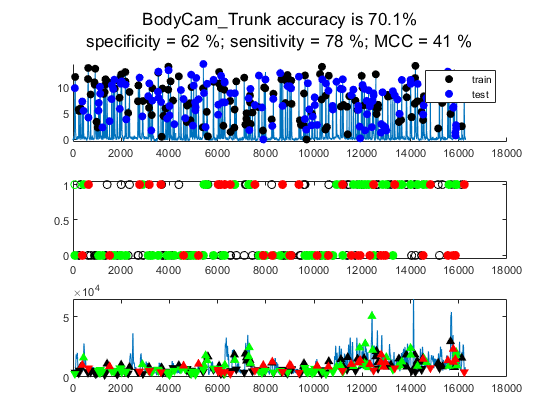

The model out-of-sample misclassification rate is 24.9%


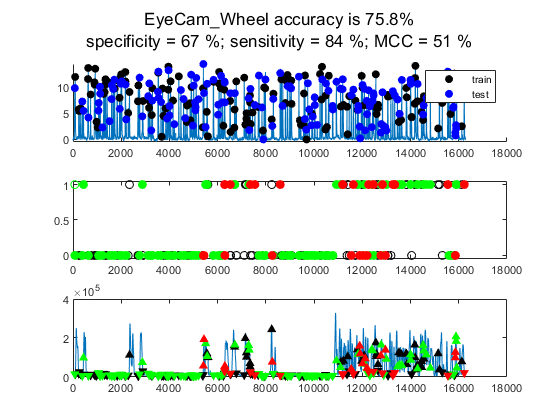

The model out-of-sample misclassification rate is 27.1%


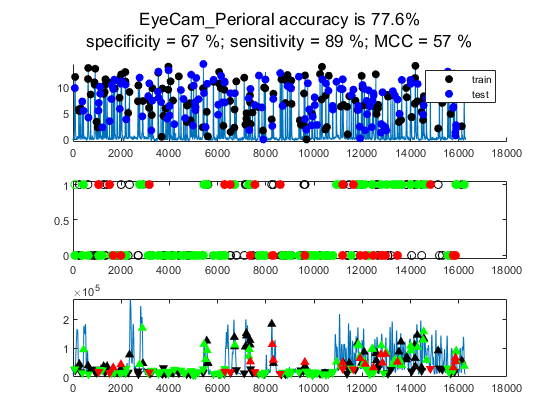

The model out-of-sample misclassification rate is 37.9%


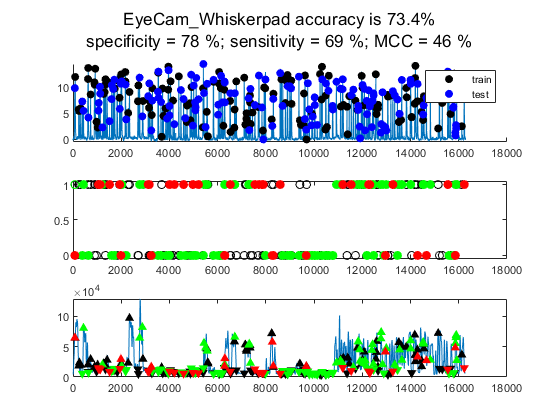

The model out-of-sample misclassification rate is 21.7%


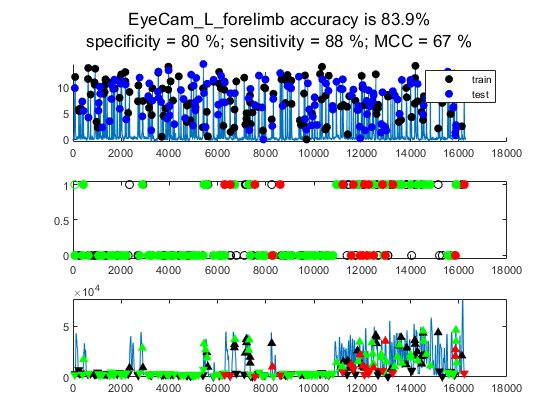

The model out-of-sample misclassification rate is 18%


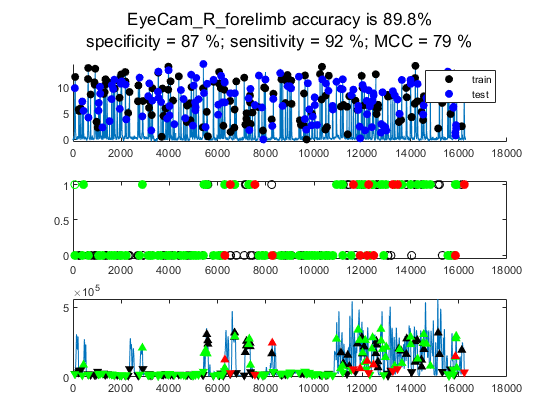

The model out-of-sample misclassification rate is 44.6%


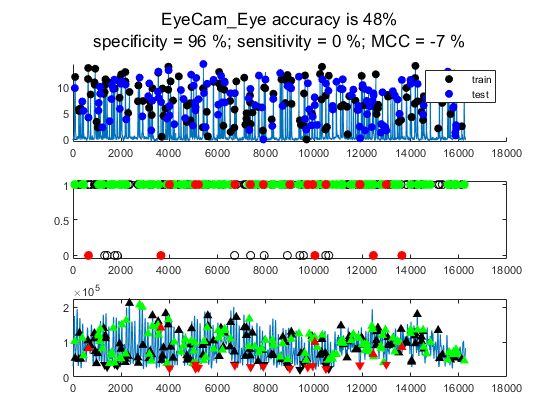

The model out-of-sample misclassification rate is 31.1%


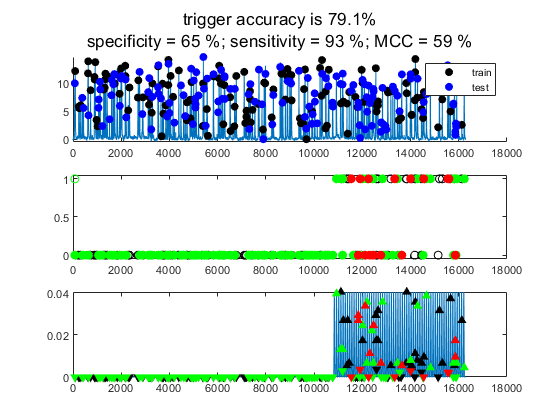

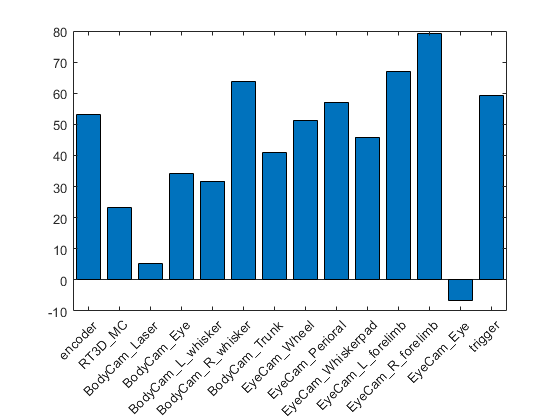

out = struct with fields:
        calcium: [16280×1 single]
        bin_beh: {1×14 cell}
        peak_tp: {[1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]}
    train_range: {1×14 cell}
     prediction: {1×14 cell}
       full_beh: {1×14 cell}
       beh_type: {'encoder'  'RT3D_MC'  'BodyCam_Laser'  'BodyCam_Eye'  'BodyCam_L_whisker'  'BodyCam_R_whisker'  'BodyCam_Trunk'  'EyeCam_Wheel'  'EyeCam_Perioral'  'EyeCam_Whiskerpad'  'EyeCam_L_forelimb'  'EyeCam_R_forelimb'  'EyeCam_Eye'  'trigger'}
          score: {1×14 cell}
          model: {1×14 cell}


% This is the default case : svm classifier
out = predict_behaviours(obj, true, 'svm')

Note that the predictor and the observations are sent to the base workspace in case you wanted to try different methods using the Classfication Learner App from MATLAB.

## Running a classifier on the rescaled peaks

The model out-of-sample misclassification rate is 29.9%
The model out-of-sample misclassification rate is 37%


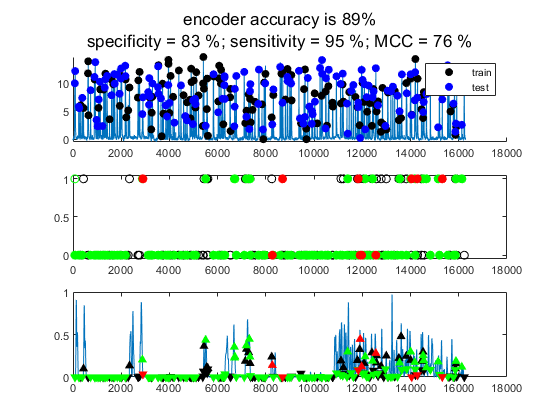

The model out-of-sample misclassification rate is 45.8%


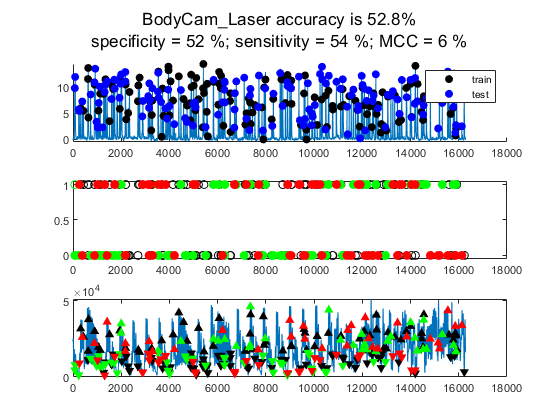

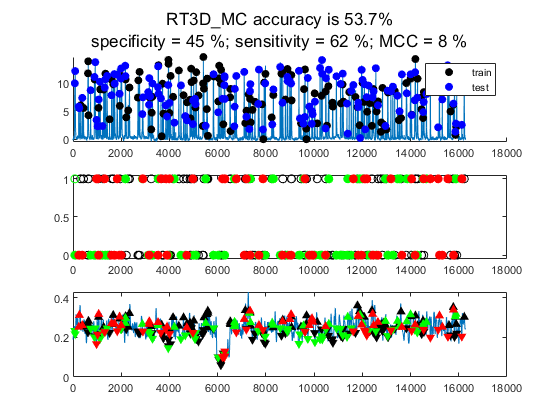

The model out-of-sample misclassification rate is 29.8%
The model out-of-sample misclassification rate is 35.2%


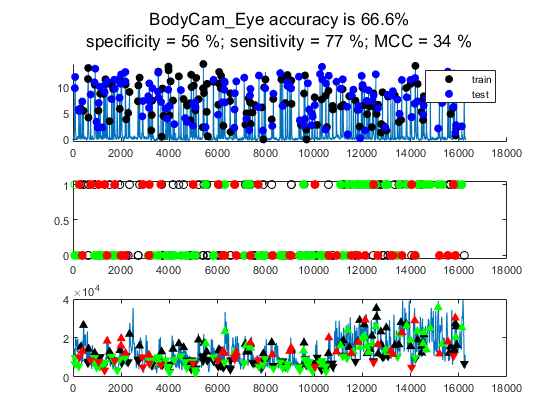

The model out-of-sample misclassification rate is 25.8%


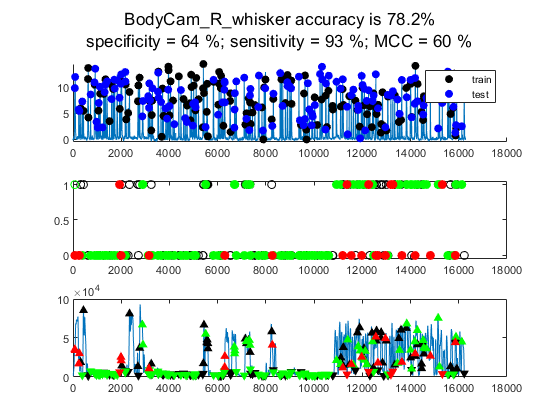

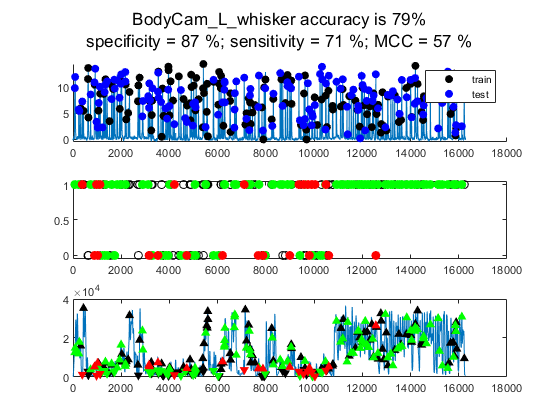

The model out-of-sample misclassification rate is 31.4%
The model out-of-sample misclassification rate is 19.1%


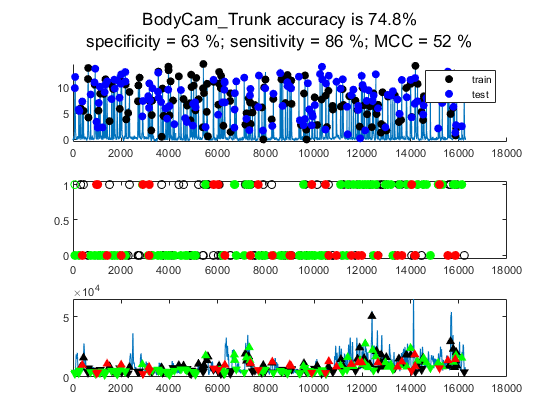

The model out-of-sample misclassification rate is 27.9%


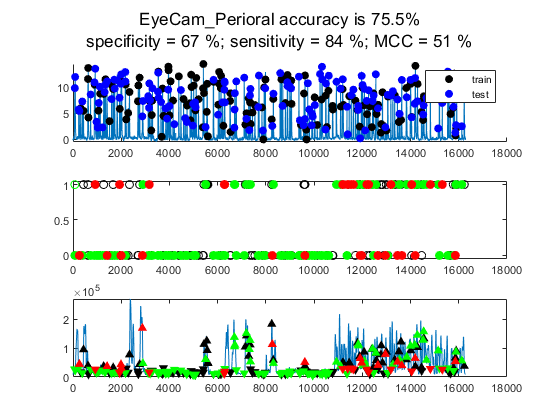

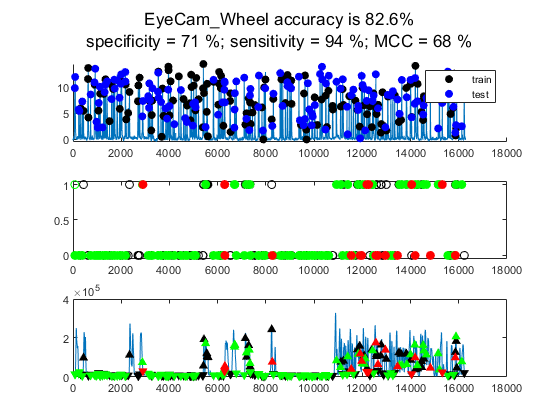

The model out-of-sample misclassification rate is 26.6%
The model out-of-sample misclassification rate is 20.9%


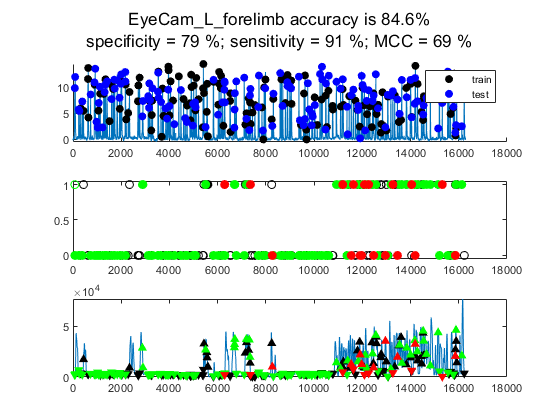

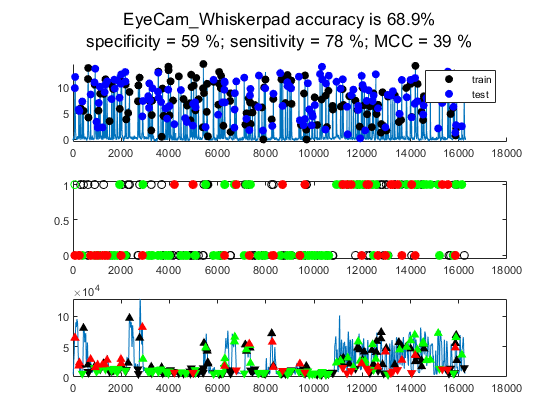

The model out-of-sample misclassification rate is 16.9%


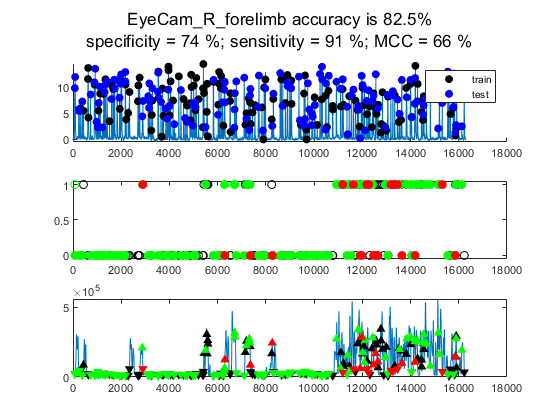

The model out-of-sample misclassification rate is 40.1%


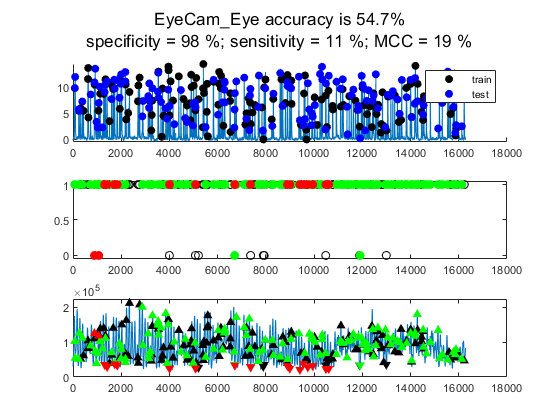

The model out-of-sample misclassification rate is 32.1%


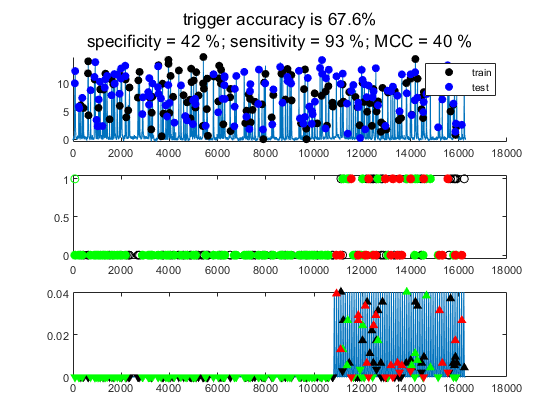

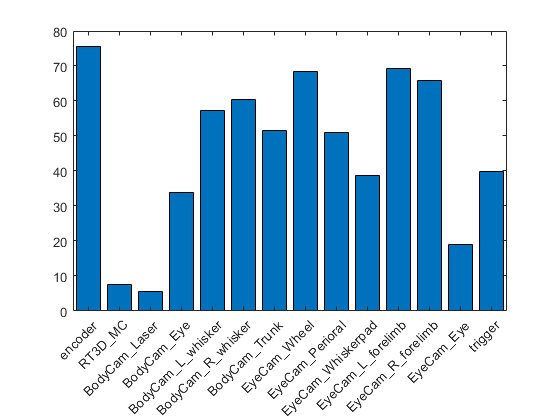

out = struct with fields:
        calcium: [16280×1 single]
        bin_beh: {1×14 cell}
        peak_tp: {[1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]  [1×276 double]}
    train_range: {1×14 cell}
     prediction: {1×14 cell}
       full_beh: {1×14 cell}
       beh_type: {'encoder'  'RT3D_MC'  'BodyCam_Laser'  'BodyCam_Eye'  'BodyCam_L_whisker'  'BodyCam_R_whisker'  'BodyCam_Trunk'  'EyeCam_Wheel'  'EyeCam_Perioral'  'EyeCam_Whiskerpad'  'EyeCam_L_forelimb'  'EyeCam_R_forelimb'  'EyeCam_Eye'  'trigger'}
          score: {1×14 cell}
          model: {1×14 cell}


% This will now take into account the magnitude of the response
out = predict_behaviours(obj, '', '', 'rescaled_peaks')

## Comparing two metrics for a given behaviour

The model out-of-sample misclassification rate is 38.9%


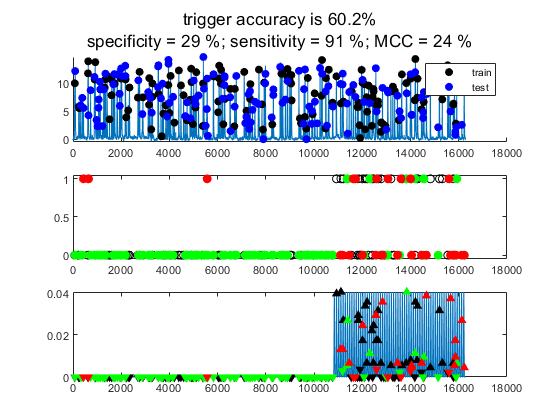

out1 = struct with fields:
        calcium: [16280×1 single]
        bin_beh: {[1×276 logical]}
        peak_tp: {[1×276 double]}
    train_range: {[276×1 logical]}
     prediction: {[138×1 logical]}
       full_beh: {[1×16280 double]}
       beh_type: {'trigger'}
          score: {[60.1974 29.1667 91.2281 23.5212]}
          model: {[1×1 classreg.learning.partition.ClassificationPartitionedModel]}


% test using peak magnitude
out1 = predict_behaviours(obj, true, 'svm','rescaled_peaks',{'trigger'})

The model out-of-sample misclassification rate is 26.1%


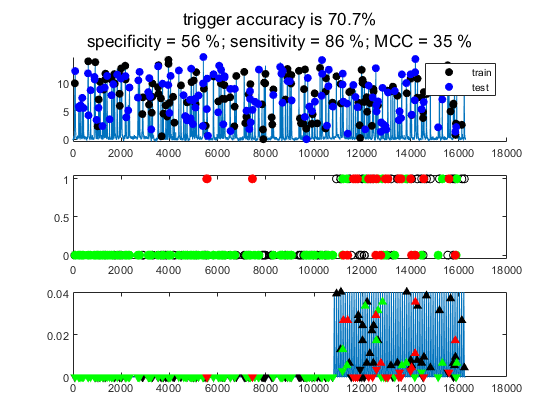

out2 = struct with fields:
        calcium: [16280×1 single]
        bin_beh: {[1×276 logical]}
        peak_tp: {[1×276 double]}
    train_range: {[276×1 logical]}
     prediction: {[138×1 logical]}
       full_beh: {[1×16280 double]}
       beh_type: {'trigger'}
          score: {[70.6944 55.5556 85.8333 35.1372]}
          model: {[1×1 classreg.learning.partition.ClassificationPartitionedModel]}


% test using changes relative to the cell median
out2 = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'})

## Train classifier on phate groups

Doing PCA
PCA using random SVD
PCA took 0.0076553 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 111
First iteration: k = 100
Number of samples below the threshold from 1st iter: 111
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.040875 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 35


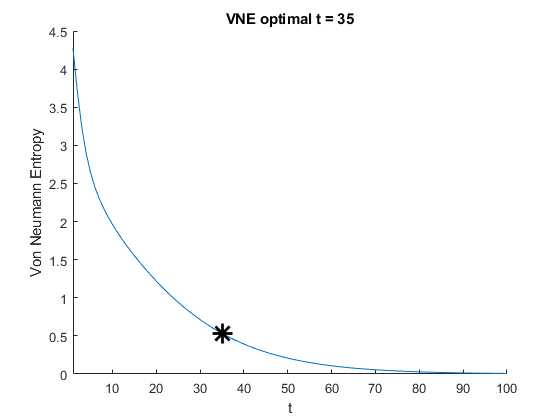

Diffusing operator
Diffusion took 0.0044988 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0081614 seconds
Doing classical MDS
CMDS took 0.0042854 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.879625       0.0443576
           1         0.23995       0.0232863         9.29208              10
           2        0.199324       0.0231994          2.2699               9
           3       0.0955866        0.032349         5.32604              12
           4       0.0727088       0.0287929         1.06492               9
           5       0.0471869       0.0256027        0.971531               9
           6       0.0257493       0.0272717         1.26207              10
           7       0.018153

tree_aspect = 'simple'

ans = 1

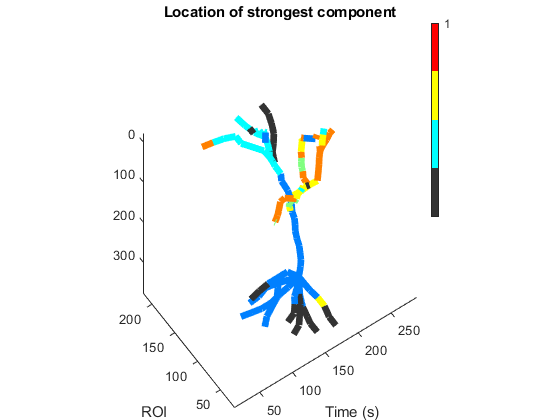

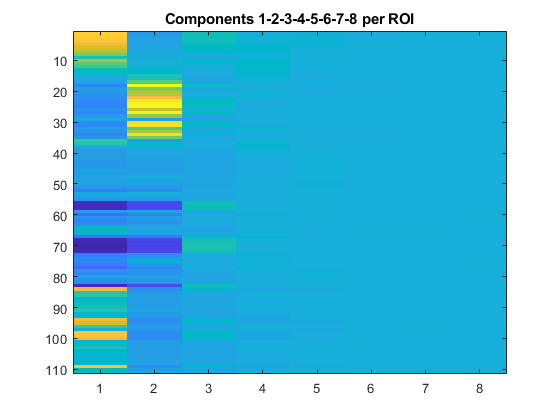

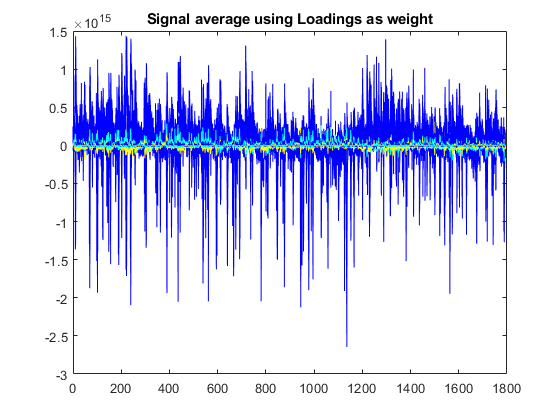

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

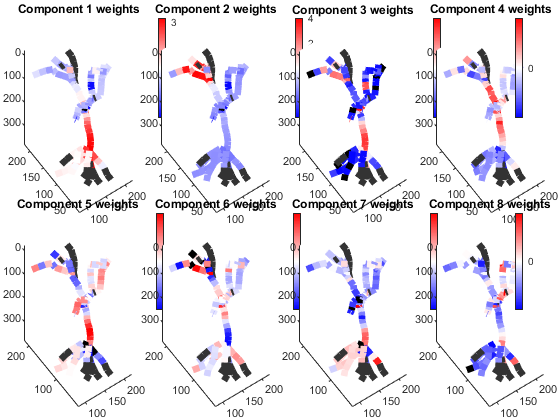

obj.get_dimensionality([], 'phate', 'peaks_subtracted', 8);

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

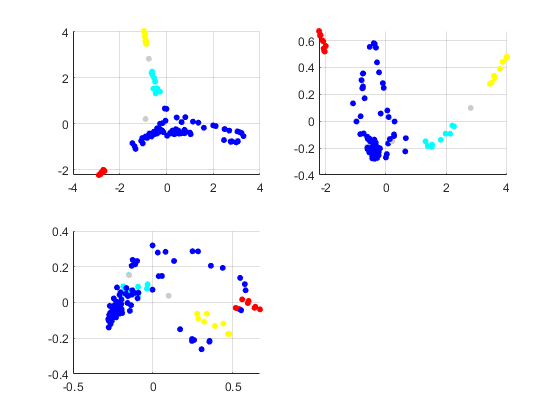

total dendritic length (-excluded branches) : 1635 um


tree_aspect = 'simple'

ans = 1

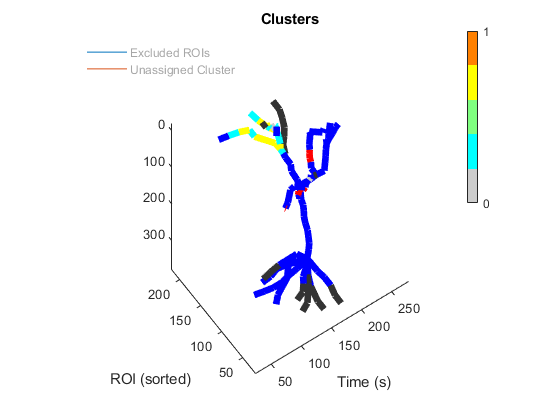

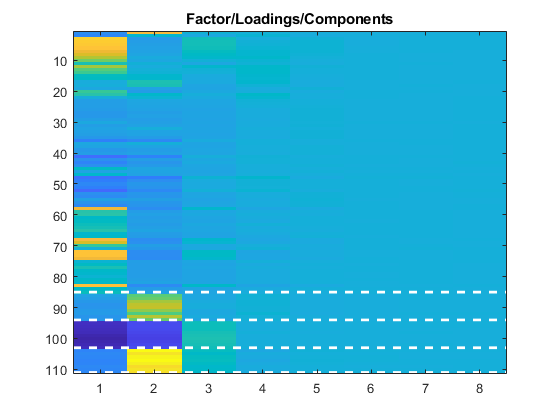

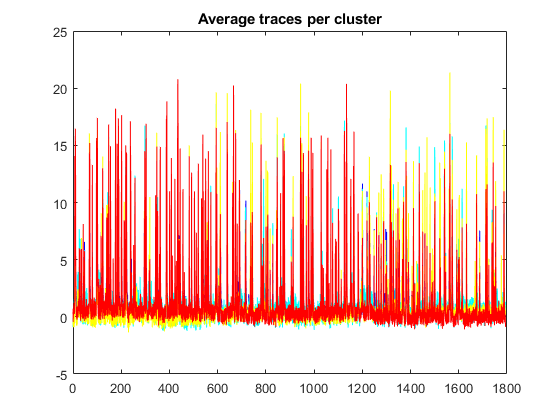

obj.cluster_factors('dbscan', []);

groups = {};
for el = 1:obj.dimensionality.N_clust
    groups{el} = find(obj.dimensionality.cluster_idx == el);
end

The model out-of-sample misclassification rate is 21.1%


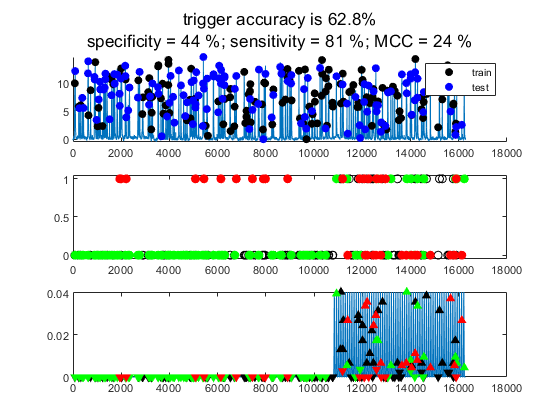

out1 = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, groups);

## Explore encoder classification using individual clusters, the average of clusters or all ROIs

optimization at : 2.5 %
optimization at : 5 %
optimization at : 7.5 %
optimization at : 10 %
optimization at : 12.5 %
optimization at : 15 %
optimization at : 17.5 %
optimization at : 20 %
optimization at : 22.5 %
optimization at : 25 %
optimization at : 27.5 %
optimization at : 30 %
optimization at : 32.5 %
optimization at : 35 %
optimization at : 37.5 %
optimization at : 40 %
optimization at : 42.5 %
optimization at : 45 %
optimization at : 47.5 %
optimization at : 50 %
optimization at : 52.5 %
optimization at : 55 %
optimization at : 57.5 %
optimization at : 60 %
optimization at : 62.5 %
optimization at : 65 %
optimization at : 67.5 %
optimization at : 70 %
optimization at : 72.5 %
optimization at : 75 %
optimization at : 77.5 %
optimization at : 80 %
optimization at : 82.5 %
optimization at : 85 %
optimization at : 87.5 %
optimization at : 90 %
optimization at : 92.5 %
optimization at : 95 %
optimization at : 97.5 %
optimization at : 100 %
The model out-of-sample misclassification 

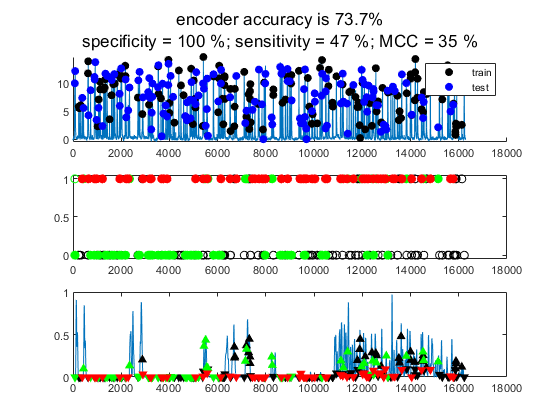

% We will use hyperparameter optimization
gp_score = {};
for gp = 1:numel(groups)
    gp_score{gp} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'encoder'}, groups{gp}, 'optimize_hyper', true, 'optimization_method', 'manual');
end

optimization at : 2.5 %
optimization at : 5 %
optimization at : 7.5 %
optimization at : 10 %
optimization at : 12.5 %
optimization at : 15 %
optimization at : 17.5 %
optimization at : 20 %
optimization at : 22.5 %
optimization at : 25 %
optimization at : 27.5 %
optimization at : 30 %
optimization at : 32.5 %
optimization at : 35 %
optimization at : 37.5 %
optimization at : 40 %
optimization at : 42.5 %
optimization at : 45 %
optimization at : 47.5 %
optimization at : 50 %
optimization at : 52.5 %
optimization at : 55 %
optimization at : 57.5 %
optimization at : 60 %
optimization at : 62.5 %
optimization at : 65 %
optimization at : 67.5 %
optimization at : 70 %
optimization at : 72.5 %
optimization at : 75 %
optimization at : 77.5 %
optimization at : 80 %
optimization at : 82.5 %
optimization at : 85 %
optimization at : 87.5 %
optimization at : 90 %
optimization at : 92.5 %
optimization at : 95 %
optimization at : 97.5 %
optimization at : 100 %
The model out-of-sample misclassification 

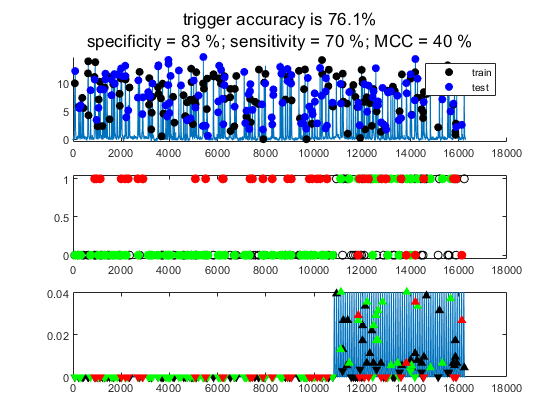


% Add score using the cluster averages as predictors
gp_score{end+1} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, groups, 'optimize_hyper', true, 'optimization_method', 'manual');

optimization at : 2.5 %
optimization at : 5 %
optimization at : 7.5 %
optimization at : 10 %
optimization at : 12.5 %
optimization at : 15 %
optimization at : 17.5 %
optimization at : 20 %
optimization at : 22.5 %
optimization at : 25 %
optimization at : 27.5 %
optimization at : 30 %
optimization at : 32.5 %
optimization at : 35 %
optimization at : 37.5 %
optimization at : 40 %
optimization at : 42.5 %
optimization at : 45 %
optimization at : 47.5 %
optimization at : 50 %
optimization at : 52.5 %
optimization at : 55 %
optimization at : 57.5 %
optimization at : 60 %
optimization at : 62.5 %
optimization at : 65 %
optimization at : 67.5 %
optimization at : 70 %
optimization at : 72.5 %
optimization at : 75 %
optimization at : 77.5 %
optimization at : 80 %
optimization at : 82.5 %
optimization at : 85 %
optimization at : 87.5 %
optimization at : 90 %
optimization at : 92.5 %
optimization at : 95 %
optimization at : 97.5 %
optimization at : 100 %
The model out-of-sample misclassification 

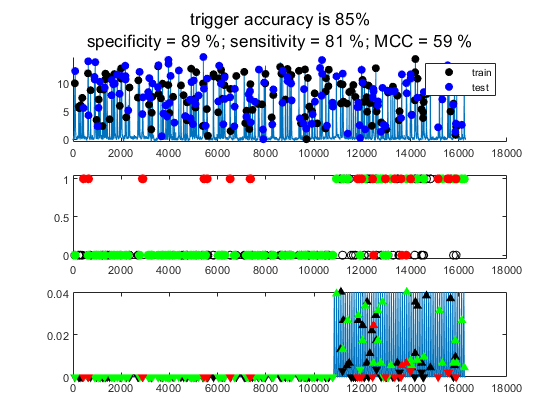


% Add score using all ROIs
gp_score{end+1} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, '', 'optimize_hyper', true, 'optimization_method', 'manual');

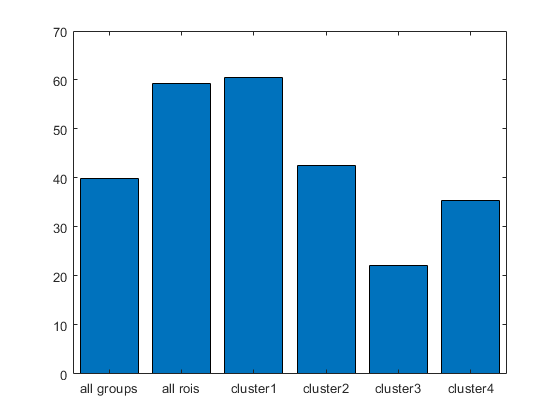

MCCs = cellfun(@(x) x.score{1}(4), gp_score);
figure(1001);clf();bar(categorical([strcat('cluster ', strsplit(num2str(1:numel(groups)),' ')),'all groups','all rois']), MCCs);

%% If you reload the results of the classifer training, you can plot the detailed prediction examples 

%% Plot classifier performances for every behaviour
for beh_idx = 1:numel(result.peak_tp)
    plot_prediction(result.calcium, result.bin_beh{beh_idx}, result.peak_tp{beh_idx}, result.train_range{beh_idx}, result.prediction{beh_idx}, result.full_beh{beh_idx}, result.beh_type{beh_idx}, result.score{beh_idx}, beh_idx);
    
    %% Comment out the pause to go faster
    pause(0)
end